# Prototype

Tadiwos made some Example code in DIP_2_with Grapgh where the rest of my code is based on.

This entire resreach we have taken the 119th frame of Video 6 Chunk 1, so the 269th grame of the video as a start point. The reason is because some movement actually starts there, which made testing out new methodes a lot easier, since we didn't have to generate a bunch of frame where we basiclt sood still first.

chunck1 = load("Imports\Ballenwerper_sync_380fps_006_chunk_1.mat"); % you may have to change your current folder
frame1 = squeeze(chunck1.video_data(1, :, :));

What was also made was a manualy created mask that of moveable parts of the machine.

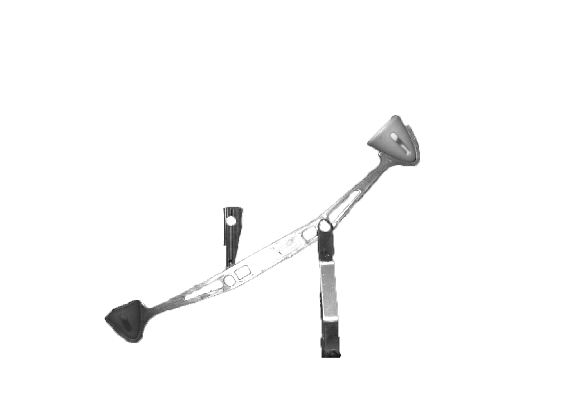

image = imread('trail.png');
imshow(image);

the image was then adited so that edge detection would work a little better

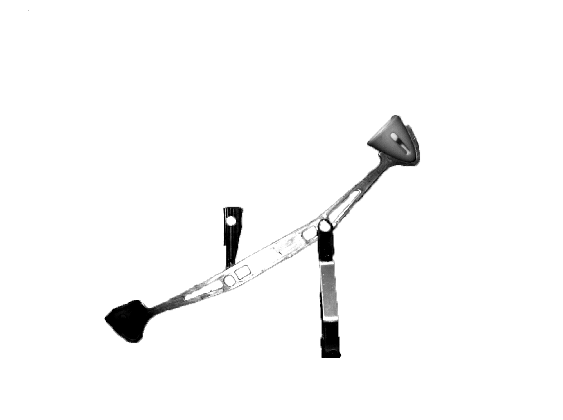

image_gray = rgb2gray(image);
image_gray = imadjust(image_gray); % Adjust contrast
image_gray = medfilt2(image_gray, [3 3]); % Apply median filter
imshow(image_gray);

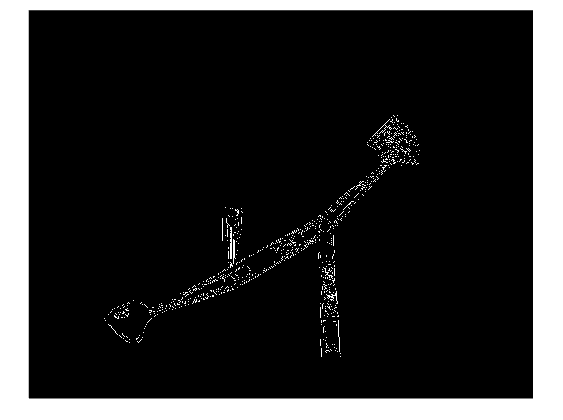


image_gray_edge = edge(image_gray, 'canny');
imshow(image_gray_edge);

this edge detection was then used to find HarrisFeatures which will be the points we try to track

points = detectHarrisFeatures(image_gray_edge);

tracker = vision.PointTracker('MaxBidirectionalError', 3);
initialize(tracker, points.Location, frame1);

Since we only care about tracking all the points in here, I won't go over the parts in the code about what happens with the data the points generate. That's for the other rapports. 

We then use the tracker in a simple way

for i = 119:150
    % Extract the next frame
    nextFrame = squeeze(chunck1.video_data(i, :, :));

    % Track points
    [newPoints, validity] = tracker(nextFrame);
    validNewPoints = newPoints(validity, :);
end

which results in this. [PLACE YOUTUBE LINK AS BACKUP]

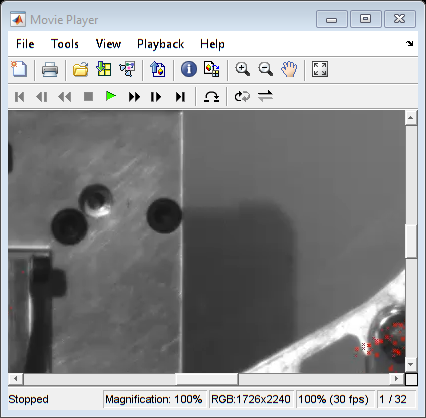

implay("Videos\OriginalTracking.mp4", 30); % VIDEO WRONG -> REMAKE

This is a good start. If run this over the whole video

%Code to make the video, comment out to spare time when pressing run.

load_video_chunks([6], true); %loads video 6 and deletes the chunks from memory when the video is made

Skipping Video_6: Already loaded.


clear;

image = imread('trail.png');

frame1 = squeeze(Video_6(119+150, :, :));

Reference to a cleared variable Video_6.


image_gray = rgb2gray(image);
image_gray = imadjust(image_gray); % Adjust contrast
image_gray = medfilt2(image_gray, [3 3]); % Apply median filter
imshow(image_gray);

image_gray_edge = edge(image_gray, 'canny');
points = detectHarrisFeatures(image_gray_edge);
tracker = vision.PointTracker('MaxBidirectionalError', 3);
initialize(tracker, points.Location, frame1);

outputVideo = VideoWriter("FullOriginalTracking.mp4", 'MPEG-4');
outputVideo.FrameRate = 30;
open(outputVideo);

for i = (119+150):1500
    % Extract the next frame
    nextFrame = squeeze(Video_6(i, :, :));

    % Track points
    [newPoints, validity] = tracker(nextFrame);
    validNewPoints = newPoints(validity, :);

    thisFrameRGB = repmat(uint8(nextFrame), [1, 1, 3]); % Convert to RGB
    thisFrameRGB = insertMarker(thisFrameRGB, validNewPoints, 'x', 'Color', 'red', 'Size', 1);

    writeVideo(outputVideo, thisFrameRGB);
end

close(outputVideo);

implay("Videos\FullOriginalTracking.mp4", 30);

We don't have that many points in the first place. And we lose a lot of them as we go on. 

What we would like is:

-detecting the entire contraption's movements

-keep the dot's consistent (so no drifting when standing still and the like)

The reason why is, if we can have all the points, then we could measure things like deformation, or similarties between runs to a very high degree. This is not needed per see, as you can see in the other raport our teams were able to work with good singular points as well. But to get a very detailed image of the deformations and the like, having all the points is better.

To this end a new folder with a new Script was started the "TrackingWholeObject" directory with "BY_TrackingPoints" being the main script.

# The Big Boi

This script looked into a lots of diffrent tools and ways to help create a video where you can show all the points of the Object being tracked.

## 1) getting more points

now that the flickering stopped, we wanted more points. A few things were tried, like layering edge detection

    SobelMask       = edge(thisFrame, 'Sobel');
    PrewittMask     = edge(thisFrame, 'Prewitt');
    RobertsMask     = edge(thisFrame, 'Roberts');
    CannyMask       = edge(thisFrame, 'Canny', [], 4);
    ApproxCannyMask = edge(thisFrame, 'approxcanny');
    % add other two

    %show startFrom269.mp4

## 2) Lighting

The flickering of the lights was an early noticed issue. This would make the point tracker work worse and make things more difficult. To fix this, we first tried [ding van vorig lab].

[show frame as example]

Afterwards, we looked into histogram equalization, and found the matlab function "histeq"

[show frame as example]

This looked better, but then we find "adapthisteq" which is essentialy "histeq" done over smaller tiles throut the image. Make it look like this

[show example frame]

And while this was nice, when in video form, we noticed that the issue wasn't really solved. Though the frames themselves became more clear. So it wasn't a wasted affored.

%show adapthisteq.mp4

Then we came up with a new idea. There are places in the video that don't move. So their brighness should be the same throut the video. Places like the first couple of rows of the frame. So, we take the avreage of these and caculate brightness of this avrage pixle. Then, every frame, we change the brigntness of the image by the amount that is needed to make those same pixles match the refrence frame.

%before we start looping through frames
topRows = 1:30;
referenceBrightness = mean(refranceFrame(topRows, :), 'all');

% processingLoop
for i = (119+150):1500
    thisFrameNotNormal = squeeze(Video_6(i, :, :));

    nextFrame = adapthisteq(thisFrameNotNormal, "Distribution", "exponential");
    
    % Normalize lighting using top rows
    currentBrightness = mean(nextFrame(topRows, :), 'all'); %mean brightes of top pixles
    adjustmentFactor = referenceBrightness / currentBrightness;
    nextFrame = nextFrame * adjustmentFactor;
    normilzedFrame = min(nextFrame, 255); % Clip to valid range

    %This was made into a funtion, so the real code it would look like:
    %normilzedFrame = normalizeFrame(thisFrameNotNormal, referenceBrightness);

    fprintf("CurentBrigness: {:d3} RefrenessBrighness: {:d3} factor: {:d}", currentBrightness, referenceBrightness, adjustmentFactor);
end

% show topframes.mp4

the refranceFrame used to be the very first frame. Later, it was change to a frame that has the median brightness of all frame. Making it so that the referenceBrightness is closer to most frames than before. More info on this frame with the median in "background".